# impédance d'entrée

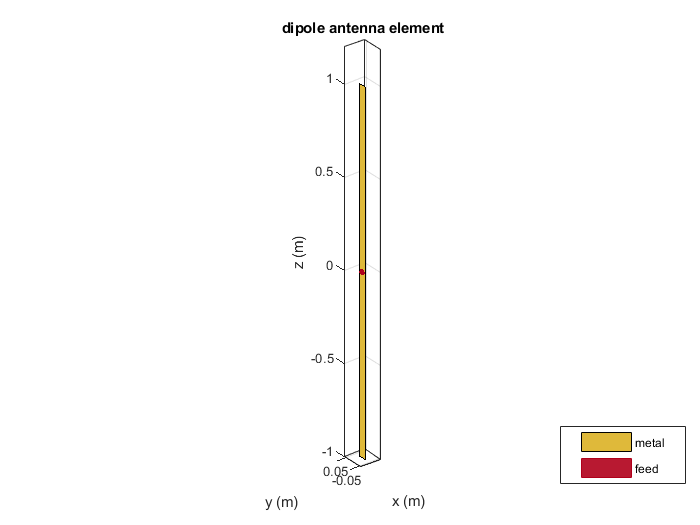


clc
clear
f = linspace(20e6, 120e6, 1000); % Frequency in Hz
lA = 2; % Dipole total length, m
a = 0.0125; % Dipole radius, m
w = cylinder2strip(a); % Eq. strip width model
d = dipole('Length',lA,'Width',w); % Strip dipole model
figure;
show(d) % Visualize geometry

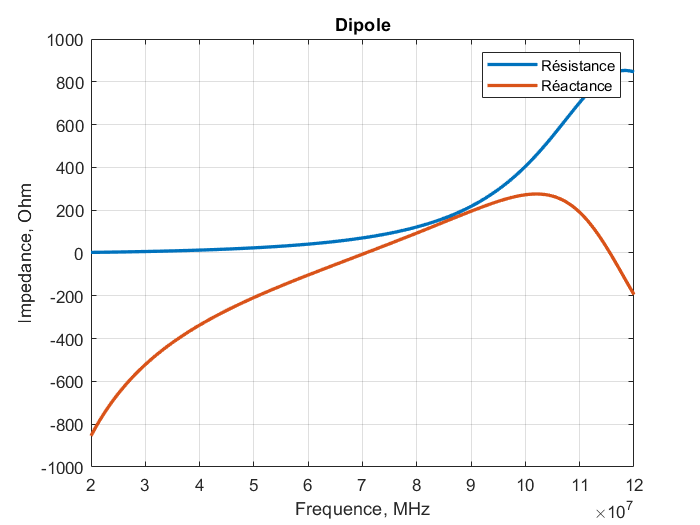

Z = impedance(d, f ); % Full-wave MoM solution
R = real(Z); % Resistance
X = imag(Z); % Reactance
figure;
plot(f,R,'LineWidth',2);
title('Dipole')
xlabel('Frequence, MHz');
ylabel('Impedance, Ohm');
grid on
hold on;
plot(f,X,'LineWidth',2);
legend('Résistance','Réactance');

## coéfficient de reflexion

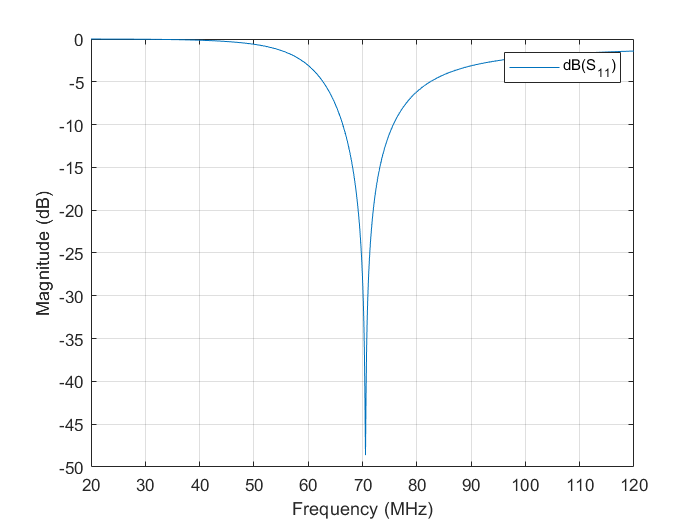


figure
Z0 = 72;
S = sparameters(d,f,Z0);
figure;
rfplot(S)

## rapport d'onde stationnaire

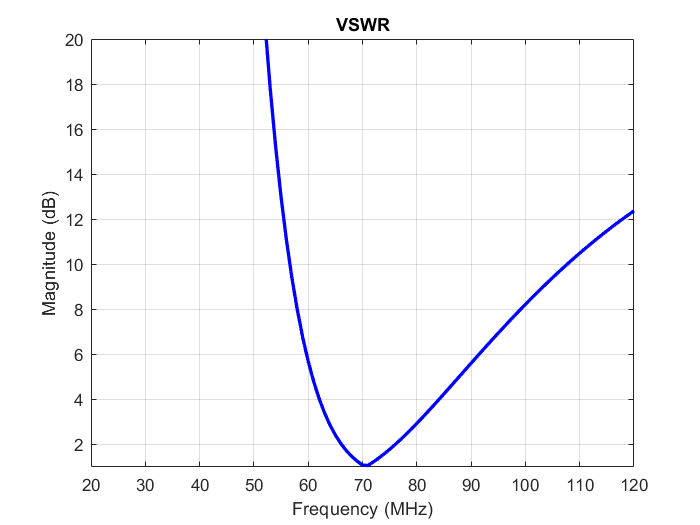


figure;
vswr(d,20e6:1e6:120e6,Z0)
axis([20 120 1 20])